**Input Image**

img=imread('peppers.png');
%camera=webcam;
%img1=snapshot(camera);
%clear 'camera'

**Show Taken Image**

imshow(img)

**Start *****Alexnet***** Neural Network**

net=alexnet;
ly=net.Layers;
clnames=net.Layers(end).ClassNames;
sz = net.Layers(1).InputSize

sz =    227   227     3


**Classify**

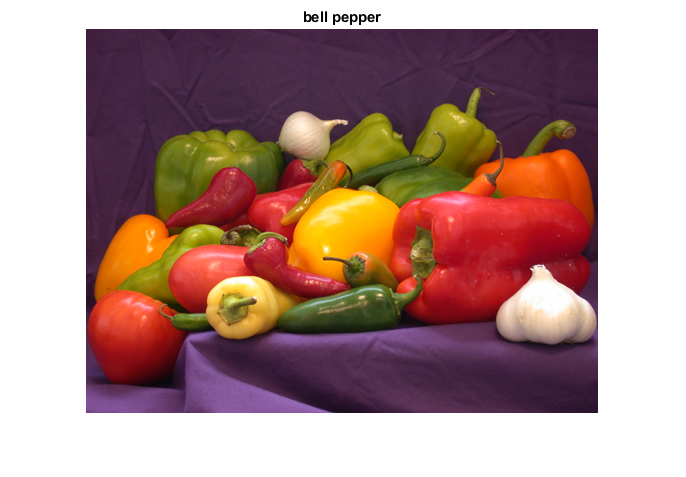

img =img(1:sz(1),1:sz(2),1:sz(3));
[label, scores1]=classify(net,img);
title(char(label))

**Prediction Bar Graph**

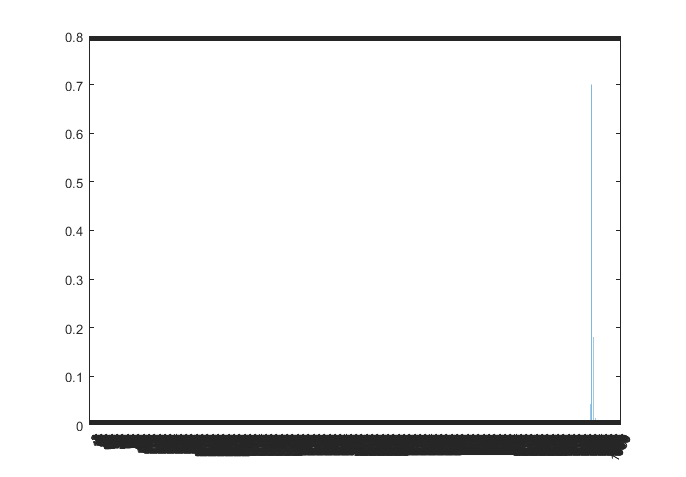

bar(scores1)
% Ensure tick values are set correctly
xticks(1:nnz(scores1))
% Rotate tick labels for readability
xtickangle(60)

**Prediction Bar Graph greater than 0.01**

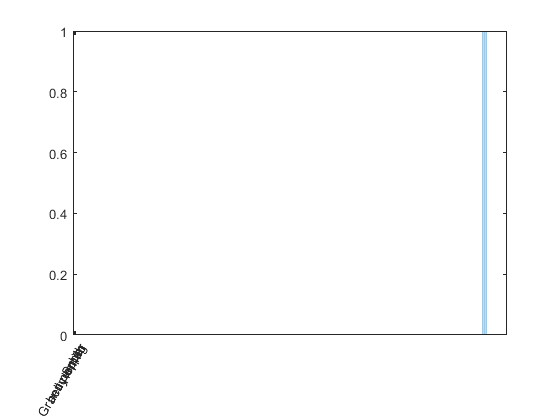

figure;
highscrores1=scores1>0.01;
bar(highscrores1);
% Ensure tick values are set correctly
xticks(1:nnz(highscrores1))
% Set tick labels
xticklabels(clnames(highscrores1))
% Rotate tick labels for readability
xtickangle(60)